Ts_roll = 1/100;
% Requirments
Mp = 0.05

Mp = 0.0500

tr = 0.25;
ts1 = 1;
zeta = sqrt((log(Mp)^2)/(log(Mp)^2+pi^2))

zeta = 0.6901

% wn = 1.8/(tr);
wn = 4.6/(zeta*ts1)

wn = 6.6656


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =   -4.6000 + 4.8240i
  -4.6000 - 4.8240i



% Plant
A_roll = [-1/t_S, 0; r_S/I_x(1), 0];
b_roll = [1/t_S; 0];
c_roll = [0,1];
d_roll = 0;

sysC_roll = ss(A_roll,b_roll,c_roll,d_roll);
% sysD_roll = c2d(sysC_roll,Ts_roll,'zoh');


Kp = 20

Kp = 20

C_roll = pid(Kp,0,0,0);
sysFB = feedback(C_roll*sysC_roll,1);
P_cl = rlocus(C_roll*sysC_roll,1)

P_cl =   -5.0000 + 4.7361i
  -5.0000 - 4.7361i


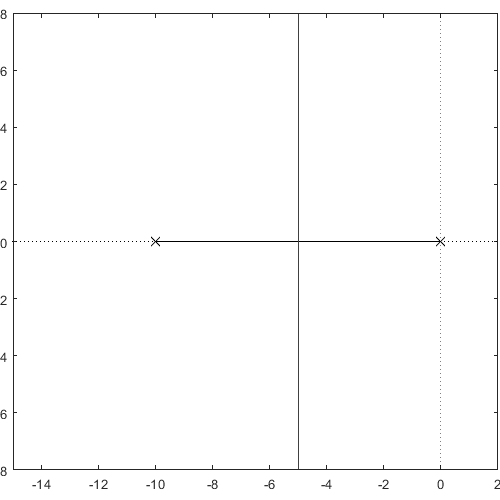

black_rlocus(sysC_roll,[])

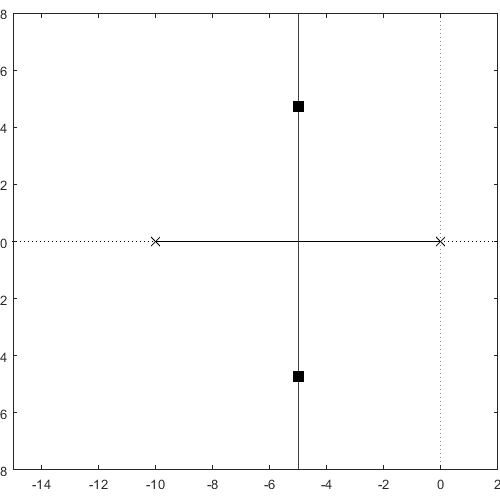

black_rlocus(C_roll*sysC_roll,P_cl)

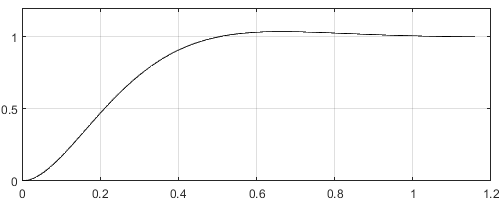

black_step(sysFB)